clear, clc, close all

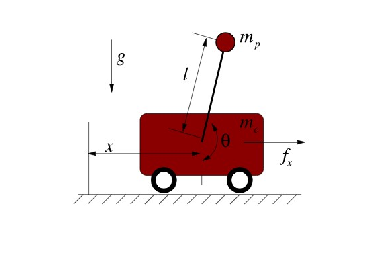

% 2 variable system, cartpole from underactuated
imshow(imread("cartpole_diagram.jpg"))


syms t x(t) t1(t) mc mp l g fx(t)
q = [x; t1]

$$q(t) = \left(\begin{array}{c} x\left(t\right)\\ t_{1}\left(t\right) \end{array}\right)$$

q_dot = diff(q,t)

$$q\_dot(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)\\ \frac{\partial }{\partial t}t_{1}\left(t\right) \end{array}\right)$$

t1_dot = diff(t1,t);
u = fx;

% Create manipulator matrices
% M(q)*q_ddot+C(q,q_dot)*q_dot = B*u + g(q)
M = [mc + mp, mp*l*cos(t1); mp*l*cos(t1), mp*l^2];
C = [0, -mp*l*t1_dot*sin(t1); 0, 0];
B = [1; 0];
tg = [0; -mp*g*l*sin(t1)];

% Solve for symbolic nonlinear q_ddot
q_ddot = simplify(inv(M)*(tg + B*u - C*q_dot));

% Check symbolic derivation against analytical from textbook
x_ddot_analytic = 1/(mc+mp*sin(t1)^2) * (fx + mp*sin(t1) * (l*t1_dot^2+g*cos(t1)))

$$x\_ddot\_analytic(t) = \frac{\mathrm{fx}\left(t\right)+\mathrm{mp}\,\sin\left(t_{1}\left(t\right)\right)\,\left(l\,{\left(\frac{\partial }{\partial t}t_{1}\left(t\right)\right)}^{2}+g\,\cos\left(t_{1}\left(t\right)\right)\right)}{\mathrm{mp}\,{\sin\left(t_{1}\left(t\right)\right)}^{2}+\mathrm{mc}}$$

t_ddot_analytic = 1/(l*(mc+mp*sin(t1)^2)) * (-fx*cos(t1)-mp*l*t1_dot^2*cos(t1)*sin(t1)-(mc+mp)*g*sin(t1))

$$t\_ddot\_analytic(t) = -\frac{l\,\mathrm{mp}\,\cos\left(t_{1}\left(t\right)\right)\,\sin\left(t_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}t_{1}\left(t\right)\right)}^{2}+\cos\left(t_{1}\left(t\right)\right)\,\mathrm{fx}\left(t\right)+g\,\sin\left(t_{1}\left(t\right)\right)\,\left(\mathrm{mc}+\mathrm{mp}\right)}{l\,\left(\mathrm{mp}\,{\sin\left(t_{1}\left(t\right)\right)}^{2}+\mathrm{mc}\right)}$$

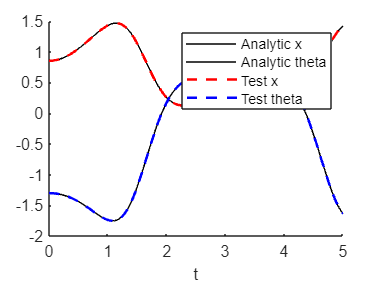


% Arbitrary functions of time
xt(t) = sin(t);
t1t(t) = cos(t);

%Subtitute into both functions
test_x = subs(x_ddot_analytic,[x(t), t1(t), mc, mp, l, g, fx],[xt, t1t, 1, 1, 1, 1, 1]);
test_t = subs(t_ddot_analytic,[x(t), t1(t), mc, mp, l, g, fx],[xt, t1t, 1, 1, 1, 1, 1]);
test_q = subs(q_ddot,[x(t), t1(t), mc, mp, l, g, fx],[xt, t1t, 1, 1, 1, 1, 1]);

% Check that output is the same
figure()
hold on
fplot(test_q,[0,5],'k-')
fplot(test_x,[0,5],'r--','LineWidth',1.5)
fplot(test_t,[0,5],'b--','LineWidth',1.5)
xlabel("t")
legend("Analytic x", "Analytic theta","Test x","Test theta")

% Now want to linearize the nonlinear equation for acceleration around
% arbitrary joint states q0 = [x0, t10] and input u0 = [fx0]
syms x0 t10 fx0 t1_var fx_var
% f(x,y) = f(x0,y0) + (x-x0)*df/dx|(x0,y0) + (y-y0)*df/dy|(x0,y0)
q_ddot0 = subs(q_ddot,[x,t1,fx],[x0, t10,fx0]);
dq_ddot_dx = subs(diff(q_ddot,x),[x,t1,fx],[x0,t10,fx0]);
dq_ddot_dt1 = subs(diff(q_ddot,t1),[x,t1,fx],[x0,t10,fx0]);
dq_ddot_dfx = subs(diff(q_ddot,fx),[x,t1,fx],[x0,t10,fx0]);
q_ddot_lin = q_ddot0 + (x-x0)*dq_ddot_dx + (t1-t10)*dq_ddot_dt1 + (fx-fx0)*dq_ddot_dfx;

% Make further analysis easier by setting all constants to 1
q_ddot_lin = subs(q_ddot_lin,[mc,mp,l,g],[1,1,1,1]);

% Plot linearization on nonlinear plot above, which in this case
% only depends on theta and fx at a given time
dq = 2;

t1_0 = 5

t1_0 = 5

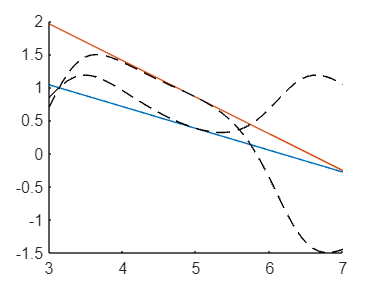

q_ddot_lin_plot_t1(t1_var) = subs(q_ddot_lin,[t1,t10,fx,fx0],[t1_var,t1_0,1,1]);
test_q_lin_t1(t1_var) = subs(q_ddot,[t1,mc,mp,l,g,fx],[t1_var,1,1,1,1,1]);
figure()
hold on
fplot(q_ddot_lin_plot_t1,[t1_0-dq,t1_0+dq])
fplot(test_q_lin_t1,[t1_0-dq,t1_0+dq],'k--')


fx_0 = 5

fx_0 = 5

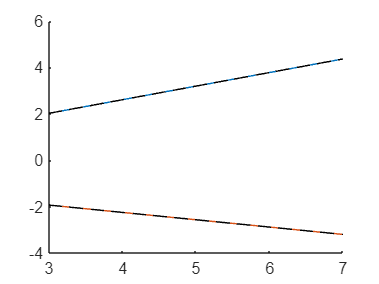

q_ddot_lin_plot_fx(fx_var) = subs(q_ddot_lin,[t1,t10,fx,fx0],[1,1,fx_var,fx_0]);
test_q_lin_fx(fx_var) = subs(q_ddot,[t1,mc,mp,l,g,fx],[1,1,1,1,1,fx_var]);
figure()
hold on
fplot(q_ddot_lin_plot_fx,[fx_0-dq,fx_0+dq])
fplot(test_q_lin_fx,[fx_0-dq,fx_0+dq],'k--')

% Now we need to assemble the linearized equation into A and B matrices for
% state space representation x_dot = Ax + Bu

% In this example, x = [delta_x, delta_theta, delta_x_dot, delta_theta_dot]
n = size(q(1),1); % n joint states
m = size(u(1),1); % m control inputs
A_lin = zeros(2*n);
B_lin = zeros(2*n,m);
A_lin(1:n,n+1:end) = eye(n); % d/dt of q is just q_dot

% Now need to collect coefficients of the linearized equation to insert
% into A_lin and B_lin
% Since it is now linear with respect to the state variables, can just get
% the coefficients with respect to each one
q_lin_body = formula(q_ddot_lin);
t1_coeffs = [coeffs(q_lin_body(1),t1);coeffs(q_lin_body(2),t1)];
x_coeffs = [coeffs(q_lin_body(1),x);coeffs(q_lin_body(2),x)]; % This is effectively zero, but would need for a general expression
u_coeffs = [coeffs(q_lin_body(1),fx);coeffs(q_lin_body(2),fx)];

% Now we can set the corresponding entries of A_lin relative to the
% coefficients 
%NEED TO LINEARIZE ArOUND VEOCITIES TOO??